Systemy dyskretne

%Uklad RLC
%[x1dot x2dot] = [0 1; -6 -5][x1 x2] + [0 6 ]u
% y = [1 0]u + [0]d
A = [0 1;-6 -5]

A =      0     1
    -6    -5


B = [0; 6]

B =      0
     6


C = [1 0]

C =      1     0


D = 0

D = 0

sysc = ss(A,B,C,D)

sysc =
 
  A = 
       x1  x2
   x1   0   1
   x2  -6  -5
 
  B = 
       u1
   x1   0
   x2   6
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



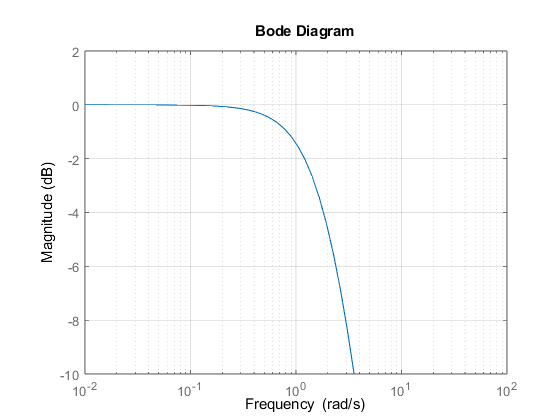

figure(1)
opts1 = bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-10 2]};
bode(sysc, opts1);
ylim([-10 1])
grid on
saveas(gcf,'1.png')

%ginput

%%Wybor okresu probkowania
omega_g = 1.5; %rad/s
f_g = omega_g / (2 * pi); %rad/s --> Hz
f_p_min = 2*f_g; %Shannon
h_max = 1 / f_p_min; % f --> Ts (okres probkowania)
h = h_max / 1; % /20

%%wyznaczamy macierze dyskretne A+ = e^(A*h), A = [0 1;-6 -5], B = [0;6]
%% przechodzimy na postać macierzy Jordana

## A+ = e^(A*h) = P * e^(J*h) * P^(-1)

A_plus = [(3*exp(-2*h)-2*exp(-3*h)) (exp(-2*h)-exp(-3*h)); 
    (-6*exp(-2*h) +6*exp(-3*h)) (-2*exp(-2*h)+ 3*exp(-3*h))]

A_plus =     0.0418    0.0133
   -0.0798   -0.0247


B_plus = [-3*exp(-2*h) + 2*exp(-3*h); 6*exp(-2* h) - 6*exp(-3* h)] - [-1;0]

B_plus =     0.9582
    0.0798


%x(k+1) = A_plus * x(k) + B_plus * u(k)
%y(k) = C*x(k)

sysd = c2d(sysc, h)

sysd =
 
  A = 
             x1        x2
   x1   0.04176    0.0133
   x2  -0.07978  -0.02473
 
  B = 
            u1
   x1   0.9582
   x2  0.07978
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 2.0944 seconds
Discrete-time state-space model.



A_plus = sysd.A

A_plus =     0.0418    0.0133
   -0.0798   -0.0247


B_plus = sysd.B

B_plus =     0.9582
    0.0798


C_plus = sysd.C

C_plus =      1     0


D_plus = sysd.D

D_plus = 0

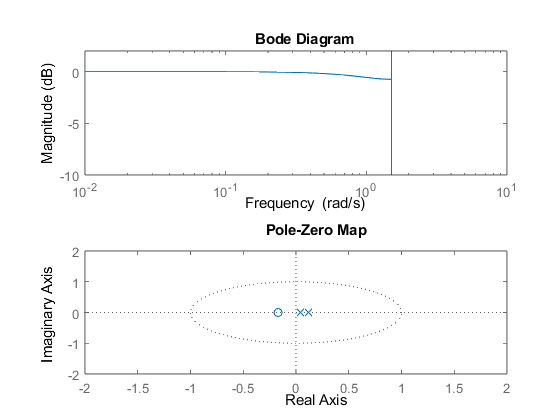

figure(2)
subplot(2,1,1)
bode(sysd, opts1)

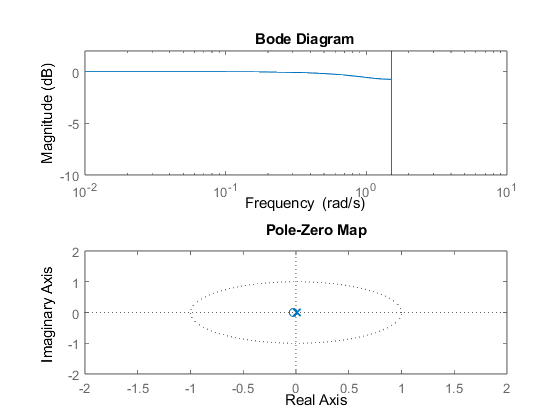

subplot(2,1,2)
pzplot(sysd)
xlim([-2 2])
ylim([-2 2])
saveas(gcf,'pzmaph_1.jpg')

%bieguny to x, sa na osi x po prawej stronie czyli stabilny bez oscylacji


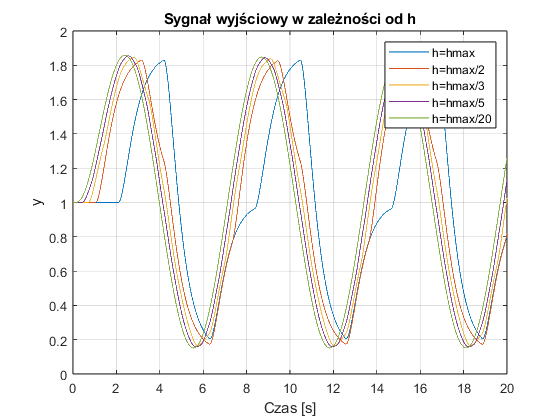

close all;
h = h_max;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout)
hold on 
h = h_max / 2;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout)
h = h_max / 3;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout)
h = h_max / 5;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout)
h = h_max / 20;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout)
grid on
xlabel("Czas [s]")
ylabel("y")
title("Sygnał wyjściowy w zależności od h")
legend("h=hmax", "h=hmax/2", "h=hmax/3", "h=hmax/5", "h=hmax/20")
hold off
saveas(gcf,'4.png')

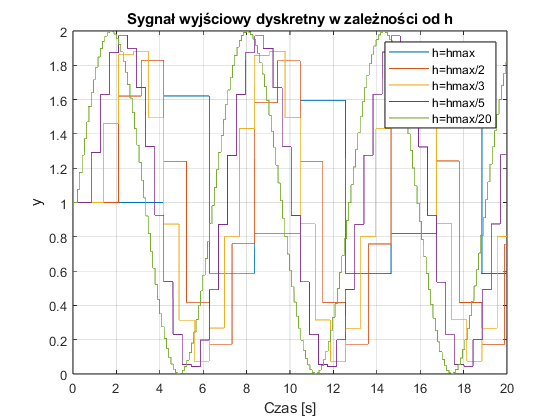

close all;
h = h_max;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout1)
hold on 
h = h_max / 2;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout1)
h = h_max / 3;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout1)
h = h_max / 5;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout1)
h = h_max / 20;
sim('dyskretne_simulink_22a.slx')
plot(tout, simout1)
grid on
xlabel("Czas [s]")
ylabel("y")
title("Sygnał wyjściowy dyskretny w zależności od h")
legend("h=hmax", "h=hmax/2", "h=hmax/3", "h=hmax/5", "h=hmax/20")
hold off
saveas(gcf,'5.png')

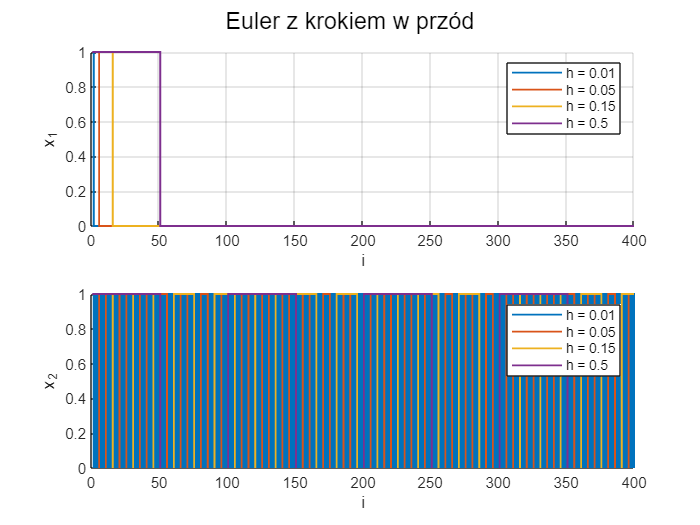

%7.2
close all;
subplot(2,1,1)
A = [-1, 0; 0, -2];
I = eye(2);
X = zeros(2,1);
X(:,1) = [1;1];
figure(1);
hold on
grid
v = [0.01, 0.05, 0.15, 0.5];
for h = v
j = 1:100*h:(round(1000/h)+1);
X = zeros(2,1);
X(:,1) = [1;1];
for i = 1:1:(length(j)-1)
X(:,i+1)= (I+1*A)*X(:,i);
% X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
% X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
end
stairs(j,X(1,:),'LineWidth', 1.1);
end
xlabel('i');
ylabel('x_1');
legend('h = 0.01','h = 0.05','h = 0.15','h = 0.5');
axis([0 400 0 1]);
%%%
subplot(2,1,2)
A = [-1, 0; 0, -2];
I = eye(2);
X = zeros(2,1);
X(:,1) = [1;1];
figure(1);
hold on
grid
v = [0.01, 0.05, 0.15, 0.5];
for h = v
j = 1:100*h:(round(1000/h)+1);
X = zeros(2,1);
X(:,1) = [1;1];
for i = 1:1:(length(j)-1)
X(:,i+1)= (I+1*A)*X(:,i);
% X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
% X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
end
stairs(j,X(2,:),'LineWidth', 1.1);
end
xlabel('i');
ylabel('x_2');
legend('h = 0.01','h = 0.05','h = 0.15','h = 0.5');
axis([0 400 0 1]);
sgtitle('Euler z krokiem w przód')
saveas(gcf,'6.png')

close all;
subplot(2,1,1)
A = [0, 1; -6, -5];
I = eye(2);
X = zeros(2,1);
X(:,1) = [2;1];
figure(1);
hold on
grid
v = [0.01, 0.05, 0.15, 0.5];
for h = 1
j = 1:100*h:(round(1000/h)+1);
X = zeros(2,1);
X(:,1) = [2;1];
for i = 1:1:(length(j)-1)
%X(:,i+1)= (I+h*A)*X(:,i);
X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
% X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
end
stairs(j,X(1,:),'LineWidth', 1.1);
end
xlabel('i');
ylabel('x_1');
legend('h = 0.01','h = 0.05','h = 0.15','h = 0.5');

axis([0 400 0 1]);
%%%
subplot(2,1,2)
A = [0, 1; -6, -5];
I = eye(2);
X = zeros(2,1);
X(:,1) = [2;1];
figure(1);
hold on
grid
v = [0.01, 0.05, 0.15, 0.5];
for h = 1
j = 1:100*h:(round(1000/h)+1);
X = zeros(2,1);
X(:,1) = [1;1];
for i = 1:1:(length(j)-1)
%X(:,i+1)= (I+h*A)*X(:,i);
X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
% X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
end
stairs(j,X(2,:),'LineWidth', 1.1);
end
xlabel('i');
ylabel('x_2');
legend('h = 0.01','h = 0.05','h = 0.15','h = 0.5');

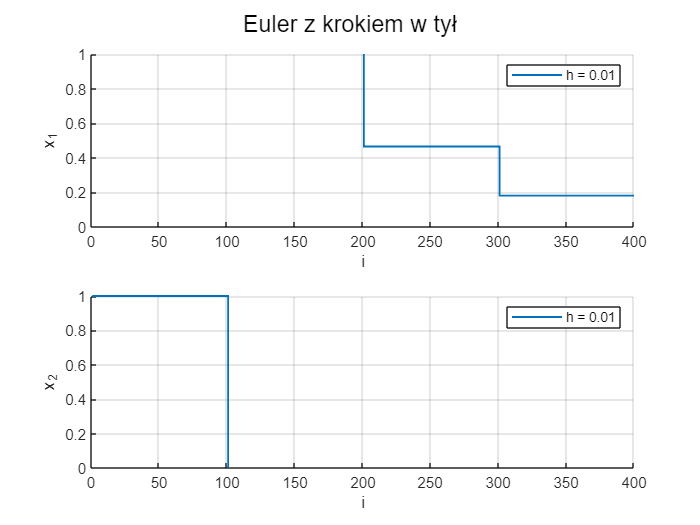

axis([0 400 0 1]);
sgtitle('Euler z krokiem w tył')
saveas(gcf,'7.png')

close all;
subplot(2,1,1)
A = [0, 1; -6, -5];
I = eye(2);
X = zeros(2,1);
X(:,1) = [2;1];
figure(1);
hold on
grid
v = [0.01, 0.05, 0.15, 0.5];
for h = 1
j = 1:100*h:(round(1000/h)+1);
X = zeros(2,1);
X(:,1) = [2;1];
for i = 1:1:(length(j)-1)
%X(:,i+1)= (I+h*A)*X(:,i);
% X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
end
stairs(j,X(1,:),'LineWidth', 1.1);
end
xlabel('i');
ylabel('x_1');
legend('h = 0.01','h = 0.05','h = 0.15','h = 0.5');

axis([0 400 0 1]);
%%%
subplot(2,1,2)
A = [0, 1; -6, -5];
I = eye(2);
X = zeros(2,1);
X(:,1) = [2;1];
figure(1);
hold on
grid
v = [0.01, 0.05, 0.15, 0.5];
for h = 1
j = 1:100*h:(round(1000/h)+1);
X = zeros(2,1);
X(:,1) = [2;1];
for i = 1:1:(length(j)-1)
%X(:,i+1)= (I+h*A)*X(:,i);
% X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
end
stairs(j,X(2,:),'LineWidth', 1.1);
end
xlabel('i');
ylabel('x_2');
legend('h = 0.01','h = 0.05','h = 0.15','h = 0.5');

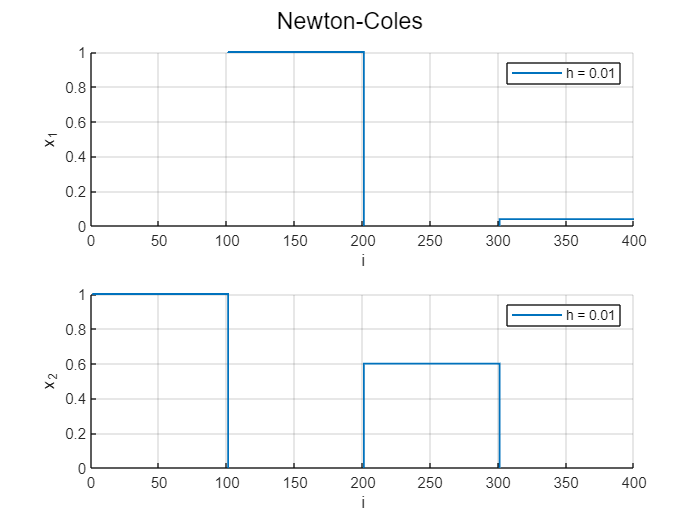

axis([0 400 0 1]);
sgtitle('Newton-Coles')
saveas(gcf,'8.png')

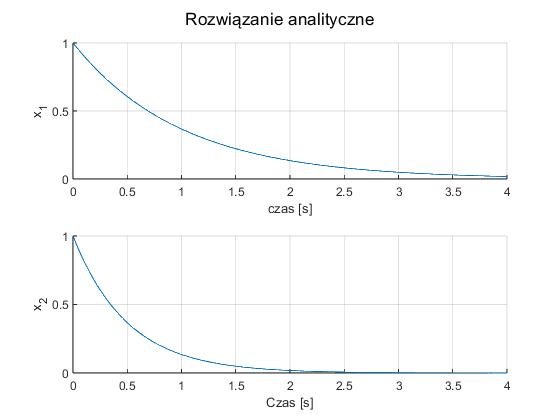

%analityczne
close all;
figure(5)
h=0.01;
ii=0:0.01:4;
jj=0:0.01:4;
x1 = zeros(1,61);
x2 = zeros(1,61);
x10 = 1;
x20 = 1;
j = 1;

for i=ii
    x1(j) = exp(-i)*x10;
    x2(j) = exp(-2*i)*x20;
    j = j+1;
end

subplot(2,1,1);
hold on;
grid on;
plot(ii,x1);
axis([0 4 0 1]);
xlabel('czas [s]');
ylabel('x_1');

subplot(2,1,2);
hold on;
grid on;
plot(ii,x2);
axis([0 4 0 1]);
xlabel('Czas [s]');
ylabel('x_2');
sgtitle('Rozwiązanie analityczne')
saveas(gcf,'9.png')

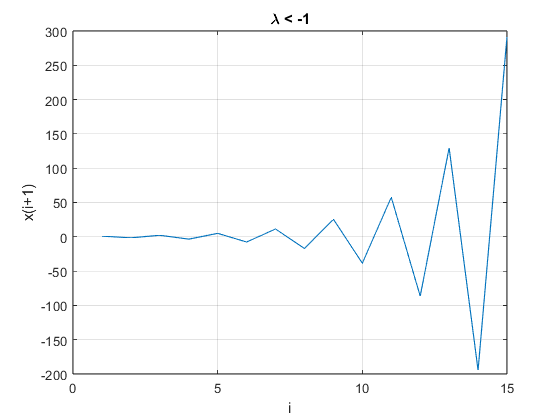

%%% Zadanie 7.3
close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;


h = -1.5;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x);
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('i');
ylabel('x(i+1)');
title('\lambda < -1')
grid on;

saveas(gcf,'10.png')

Error using print
Functionality not supported with figures created with the uifigure function.

Error in saveas (line 181)
        print( h, name, ['-d' dev{i}] )

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = -1;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x);
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('i');
ylabel('x(i+1)');
title('\lambda = -1')
grid on;
saveas(gcf,'11.png')

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = -0.5;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x);
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('i');
ylabel('x(i+1)');
title('\lambda = -0.5')
grid on;
saveas(gcf,'12.png')

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = 0;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x);
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('i');
ylabel('x(i+1)');
title('\lambda = 0')
grid on;
saveas(gcf,'13.png')

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = 0.5;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x);
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('i');
ylabel('x(i+1)');
title('\lambda = 0.5')
grid on;
saveas(gcf,'14.png')

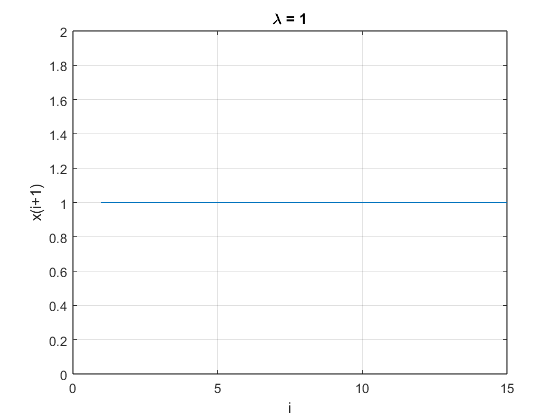

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = 1;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x);
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('i');
ylabel('x(i+1)');
title('\lambda = 1')
grid on;
saveas(gcf,'15.png')

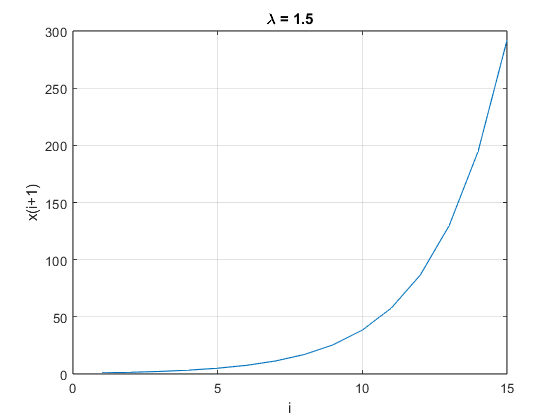

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = 1.5;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x);
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('i');
ylabel('x(i+1)');
title('\lambda = 1.5')
grid on;
saveas(gcf,'16.png')


%xdot = Ax(k) = (x(k+1)-x(k)) / h
%x(k+1) -x(k) = h*A*x(k)
%x(k+1) = (I + h*A)x(k)
%A = [-1 0;0 -2]
%A_dyskretna = I + A*h
%dla różnych h sprawdzamy wartości własne
